## 12 software engineering hacks for your MATLAB experience

sdgdfg

### New Data Types

#### strings

Imagine that you're teaching a course of students, and you want to manage the class list in MATLAB

Historically, you might use a combination of character arrays and cell arrays...

CourseStudentNames = {...
    'Alessandro','Rossi';...
    'Wang', 'Li';...
    'Devi', 'Singh';...
    'María', 'García';...
    'Adebayo', 'Oluwafemi';...
    'João', 'Silva'}

CourseStudentNames = 6×2 cell array
    {'Alessandro'}    {'Rossi'    }
    {'Wang'      }    {'Li'       }
    {'Devi'      }    {'Singh'    }
    {'María'     }    {'García'   }
    {'Adebayo'   }    {'Oluwafemi'}
    {'João'      }    {'Silva'    }


These were commonly referred to as "cell strings" Strings, introduced in R2016 are much easier to use and manage, and provide a lot more functionality.  Use a double quote, rather than a single quote, and you can put them right into an array:

  CourseStudentNames = [...
    "Alessandro","Rossi";...
    "Wang", "Li";...
    "Devi", "Singh";...
    "María", "García";...
    "Adebayo", "Oluwafemi";...
    "João", "Silva"]

CourseStudentNames = 6×2 string array
    "Alessandro"    "Rossi"    
    "Wang"          "Li"       
    "Devi"          "Singh"    
    "María"         "García"   
    "Adebayo"       "Oluwafemi"
    "João"          "Silva"    


Manipulating strings is much easier and intuitive than cell arrays of chars

FirstName = CourseStudentNames(:,1);
LastName = CourseStudentNames(:,2);
FullName = FirstName + " " + LastName

FullName = 6×1 string array
    "Alessandro Rossi"
    "Wang Li"
    "Devi Singh"
    "María García"
    "Adebayo Oluwafemi"
    "João Silva"


In R2020b, a set of powerful text parsing and pattern matching tools were introduced.  Here's just quick taste of what you can do.  Imagine, for fun, you wanted to chose the order of class presentations by the number of vowels a student's name had:

FullName

FullName = 6×1 string array
    "Alessandro Rossi"
    "Wang Li"
    "Devi Singh"
    "María García"
    "Adebayo Oluwafemi"
    "João Silva"


VowelCount = count(FullName,...
    characterListPattern("aãeiíou"))

VowelCount =      5
     2
     3
     6
     7
     5


### table

How do you keep track of related data that have different types?  Historically, you could use struct, but there's a lot of messiness there when you want to work with a lot of data.  

course = struct("FirstName",cellstr(FirstName),...
    "LastName",cellstr(LastName))

course = 6×1 struct array with fields:
    FirstName
    LastName


tables, introduced in R2013b with significant performance increases in R2019b, are a natural way to manage tabular data of different types:

course = table(FirstName,LastName)

course = 6×2 table
     FirstName       LastName  
    ____________    ___________

    "Alessandro"    "Rossi"    
    "Wang"          "Li"       
    "Devi"          "Singh"    
    "María"         "García"   
    "Adebayo"       "Oluwafemi"
    "João"          "Silva"    


Let's add our number of vowels and find out who's presenting first:

course

course = 6×2 table
     FirstName       LastName  
    ____________    ___________

    "Alessandro"    "Rossi"    
    "Wang"          "Li"       
    "Devi"          "Singh"    
    "María"         "García"   
    "Adebayo"       "Oluwafemi"
    "João"          "Silva"    


course.NumberOfVowels = VowelCount;
sortrows(course,"NumberOfVowels","descend")

ans = 6×3 table
     FirstName       LastName      NumberOfVowels
    ____________    ___________    ______________

    "Adebayo"       "Oluwafemi"          7       
    "María"         "García"             6       
    "Alessandro"    "Rossi"              5       
    "João"          "Silva"              5       
    "Devi"          "Singh"              3       
    "Wang"          "Li"                 2       


Adebayo is going to be first!

#### Datetime and Duration

Historically, MATLAB managed time information using datenum, which was a numeric value tied to the calendar.   

dueDate = datenum("2023-11-22 23:59:00")

dueDate = 7.3921e+05

In R2014b, datetime and duration were added, which include powerful functions for managing timestamps across timezones.  Let's imagine we have a paper that's due at 11:59 on November 22.  How much time is left? 

dueDate = datetime("2023-11-22 23:59:00")

dueDate = datetime
   22-Nov-2023 23:59:00


dueDate - datetime("now")

ans = duration
   150:58:42


datetimes represent a specific date and time, durations represent a span of time between two dates, usually shown in hours:

Actually, it's an online class, and the students are from around the world.  Our deadline is Central European time, but the students submitted their work all over the world in different time zones -- did they make it?

dueDate.TimeZone = "Europe/Rome";

 Let's add a a record of when people submitted in their local time zone to each student

course.PaperSubmitted = [...
    datetime("2023-11-22 03:00", "TimeZone","Europe/Rome");...
    datetime("2023-11-23 06:00", "TimeZone","Asia/Hong_Kong");...
    datetime("2023-11-22 20:00", "TimeZone","Asia/Calcutta");...
    datetime("2023-11-22 20:00", "TimeZone","Europe/Madrid");...
    datetime("2023-11-23 00:30", "TimeZone","Africa/Harare");...
    datetime("2023-11-22 21:00", "TimeZone","America/Sao_Paulo")]

course = 6×4 table
     FirstName       LastName      NumberOfVowels       PaperSubmitted   
    ____________    ___________    ______________    ____________________

    "Alessandro"    "Rossi"              5           22-Nov-2023 03:00:00
    "Wang"          "Li"                 2           22-Nov-2023 23:00:00
    "Devi"          "Singh"              3           22-Nov-2023 15:30:00
    "María"         "García"             6           22-Nov-2023 20:00:00
    "Adebayo"       "Oluwafemi"          7           22-Nov-2023 23:30:00
    "João"          "Silva"              5           23-Nov-2023 01:00:00


Note that MATLAB automatically converted everything to the same time zone so we can easily compare them

course.OnTime = course.PaperSubmitted < dueDate

course = 6×5 table
     FirstName       LastName      NumberOfVowels       PaperSubmitted       OnTime
    ____________    ___________    ______________    ____________________    ______

    "Alessandro"    "Rossi"              5           22-Nov-2023 03:00:00    true  
    "Wang"          "Li"                 2           22-Nov-2023 23:00:00    true  
    "Devi"          "Singh"              3           22-Nov-2023 15:30:00    true  
    "María"         "García"             6           22-Nov-2023 20:00:00    true  
    "Adebayo"       "Oluwafemi"          7           22-Nov-2023 23:30:00    true  
    "João"          "Silva"              5           23-Nov-2023 01:00:00    false 


Sorry, João -- even though you submitted before the deadline in local time, the deadline has already passed.

#### timetable

load BicycleCounts.mat
bikeData

bikeData = 284623×3 timetable
          DateTime          Westbound    Eastbound     Weekday 
    ____________________    _________    _________    _________

    18-Jan-2022 00:00:00        0            0        Tuesday  
    18-Jan-2022 00:15:00        0            0        Tuesday  
    18-Jan-2022 00:30:00        0            0        Tuesday  
    18-Jan-2022 00:45:00        0            0        Tuesday  
    18-Jan-2022 01:00:00        0            0        Tuesday  
    18-Jan-2022 01:15:00        0            0        Tuesday  
    18-Jan-2022 01:30:00        0            0        Tuesday  
    18-Jan-2022 01:45:00        0            0        Tuesday  
    18-Jan-2022 02:00:00        0       

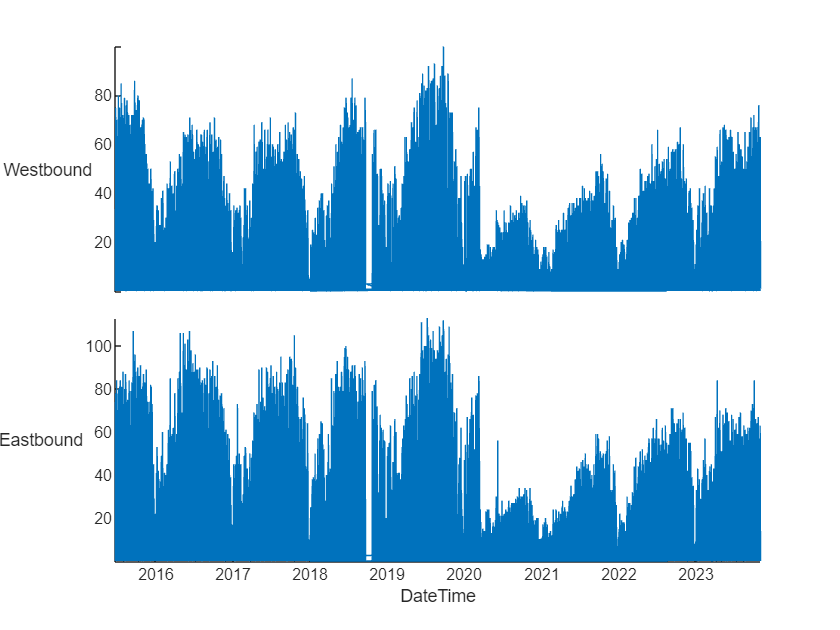

stackedplot(bikeData)

bikeData.TimeOfDay = timeofday(bikeData.DateTime);

% Compute group summary
averageDay = groupsummary(bikeData,"TimeOfDay","hour","median",vartype("numeric"));
averageDay.GroupCount = []

averageDay = 24×3 table
       hour_TimeOfDay       median_Westbound    median_Eastbound
    ____________________    ________________    ________________

    [00:00:00, 01:00:00)           1                    0       
    [01:00:00, 02:00:00)           0                    0       
    [02:00:00, 03:00:00)           0                    0       
    [03:00:00, 04:00:00)           0                    0       
    [04:00:00, 05:00:00)           0                    0       
    [05:00:00, 06:00:00)           0                    1       
    [06:00:00, 07:00:00)           0                    3       
    [07:00:00, 08:00:00)           2                    9       
    [08:00:00, 09:00:00)           3                   21       
    [09:00:00, 10:00:00)           3                   14       
    [10:00:00, 11:00:00)           3                    7       
    [11:00:00, 12:00:00)    

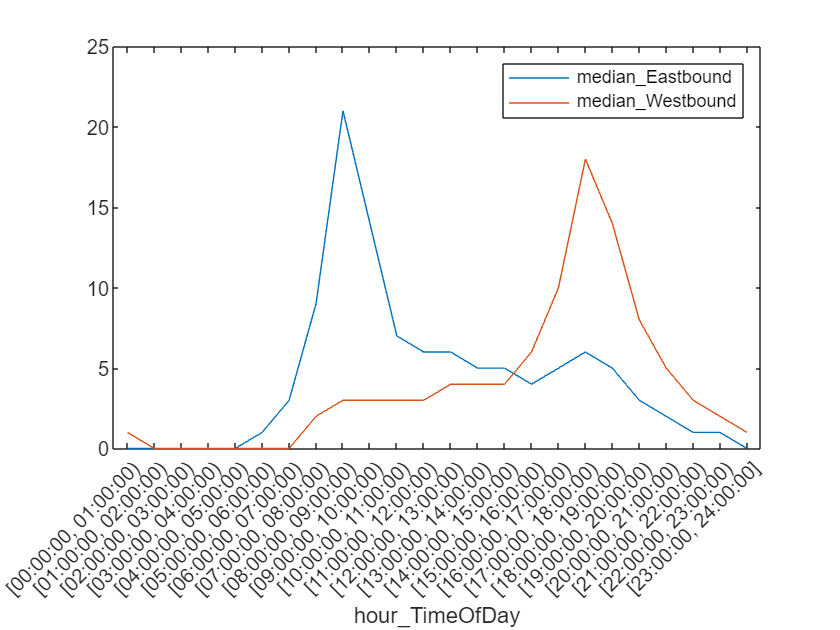

plot(averageDay,"hour_TimeOfDay",["median_Eastbound","median_Westbound"]) 
legend

### Reliability

#### function blocks

Let's go back to our class.  They took their first test, and it didn't really go well

Test1Raw = [78;86;72;88;74;67];
course = table(FirstName,LastName,Test1Raw);
course

course = 6×3 table
     FirstName       LastName      Test1Raw
    ____________    ___________    ________

    "Alessandro"    "Rossi"           78   
    "Wang"          "Li"              86   
    "Devi"          "Singh"           72   
    "María"         "García"          88   
    "Adebayo"       "Oluwafemi"       74   
    "João"          "Silva"           67   


cd applyCurveV1

The professor decides to apply a simple curve, and writes a function to do it:

type applyCurve.m

function curvedGrade = applyCurve(grade)
    curvedGrade = grade + (85 - median(grade,1));
end














applyCurve(course.Test1Raw)

ans =     87
    95
    81
    97
    83
    76


Works great!  But the skill I want you all to cultivate is the nasty, cynical, bad person who asks “what if” – and tries to break things.  For example, our little function goes terribly wrong if you pass in a horizontal vector.

applyCurve(course.Test1Raw')

ans =     85    85    85    85    85    85


cd ..\applyCurveV2

Time for validation.  We add an argument block, and specify that the grade parameter must be a vertical vector of doubles:

type applyCurve.m

function curvedGrade = applyCurve(grade)
    arguments
        grade (:,1) double
    end
    curvedGrade = grade + (85 - median(grade,1));
end














Suddenly, everything works better -- because it not only checks to see if the inputs are valid, but it attempts to put them in the right format if it can:

The horizontal vector from earlier is fixed

applyCurve(course.Test1Raw')

ans =     87
    95
    81
    97
    83
    76


If we pass in something that can be converted to double, it is

applyCurve(["10","20","30"])

ans =     75
    85
    95


Even fairly esoteric things, like hexidecimal numbers.... did you know that MATLAB does that?

applyCurve([0x23 0x35])

ans =     76
    94


cd ..\applyCurveV3

applyCurve(course.Test1Raw)

ans =     87
    95
    81
    97
    83
    76


applyCurve(course.Test1Raw,87.5)

ans =    89.5000
   97.5000
   83.5000
   99.5000
   85.5000
   78.5000


cd ..